# PHYS 449: time evolution of string states on a noncommutative sphere

## Theory

The noncommutative sphere is defined by the three angular momentum operators $J_x, J_y, J_z$,  which satisfy:


$$[J_i, J_j] = i\epsilon^{ijk} J_k$$


and


$$J_x^2 + J_y^2 + J_z^2 = \frac{1}{4}(j^2-1)I$$


The matrix elements of these operators are the dynamical variables. For example, if $|x \rangle$ is a coherent state, then $\langle x | \mathbf{J} | x \rangle$represents the position of the state $|x \rangle$. 

A string state $\Phi$ is represented by an $N \times N$ matrix corresponding to the outer product of two coherent states


$$\Phi = | a \rangle \langle b|$$


where a coherent state $|a \rangle$is the eigenstate corresponding to the largest eigenvalue of the angular momentum operator in the direction of some unit vector $\hat{n}$: $J_{\hat{n}} = \hat{n} \cdot \mathbf{J}$

The potential is


$$V = -Tr([J_i, \Phi]^2) + \frac{m^2}{2}Tr(\Phi^2)$$


The Lagrangian that governs the time evolution of a string state is given by


$$\mathcal{L} = \frac{1}{2} Tr(\dot{\Phi}^2) + Tr([J_i, \Phi]^2)$$


This gives the equation of motion


$$\ddot{\Phi} =-(\nabla^2 + m^2)\Phi$$


where $\nabla^2 \Phi = [\mathbf{J}, [\mathbf{J}, \Phi]]$.

## Solving the EOM numerically with ode45

First, turn the second order differential equation into two first order equations


$$\frac{d}{\mathrm{dt}}\left\lbrack \begin{array}{c}
\Phi \\
\Phi^˙ 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\Phi^˙ \\
-\left(\nabla^2 +m^2 \right)\Phi 
\end{array}\right\rbrack$$
 

this can be solved numerically using ode45.

Note that since $y=\left\lbrack \begin{array}{c}
\Phi \\
\Phi^˙ 
\end{array}\right\rbrack$must be a column vector for ode45, I reshape $\Phi$ so that it is an $N^2 \times 1$ column vector formed by stacking the columns of $\Phi$ on top of each other in order.

## Computations

### 3x3 Angular momentum matrices 

N = 3;
J = JMatrices(N)

J =   JMatrices with properties:

    x: [3×3 double]
    y: [3×3 double]
    z: [3×3 double]


J.x

ans =          0    0.7071         0
    0.7071         0    0.7071
         0    0.7071         0


J.y

ans =    0.0000 + 0.0000i   0.0000 - 0.7071i   0.0000 + 0.0000i
   0.0000 + 0.7071i   0.0000 + 0.0000i   0.0000 - 0.7071i
   0.0000 + 0.0000i   0.0000 + 0.7071i   0.0000 + 0.0000i


J.z

ans =      1     0     0
     0     0     0
     0     0    -1


### Coherent states at North and South poles

n1 = [0, pi/2, 1];   % North pole
n2 = [0, -pi/2, 1];  % South pole

a = CoherentState(J, n1, CoordType.spherical);
b = CoherentState(J, n2, CoordType.spherical);
Phi = StringState(a, b);

m = 1;

### Solving the EOM

tspan = [0, 10];
dPhi_dt_0 = zeros(N);
y0 = [Phi.M(:); dPhi_dt_0(:)];
[t, y] = solveEOM(tspan, y0, m, J)

t =          0
    0.0072
    0.0144
    0.0215
    0.0287
    0.0646
    0.1005
    0.1364
    0.1722
    0.3517


y =     0.0000    0.0000    1.0000    0.0000    0.0000    0.0000    1.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0
    0.0000    0.0000    1.0000    0.0000    0.0000    0.0000    1.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0001   -0.0000   -0.0000   -0.0000   -0.0001   -0.0000   -0.0000
    0.0000    0.0000    1.0000    0.0000    0.0000    0.0000    1.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0001   -0.0000   -0.0000   -0.0000   -0.0001   -0.0000   -0.0000
    0.0000    0.0000    1.0000    0.0000    0.0000    0.0000    1.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0002   -0.0000   -0.0000   -0.0000   -0.0002   -0.0000   -0.0000
    0.0000    0.0000    1.0000    0.0000    0.0000    0.0000    1.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0002   -0.0000   -0.0000   -0.0000   -0.0002   -0.0000   -0.0000
    0.0000    0.0000    1.0000    0.0000    0.0000    0.0000    1.0000    0.0000    0.0000 

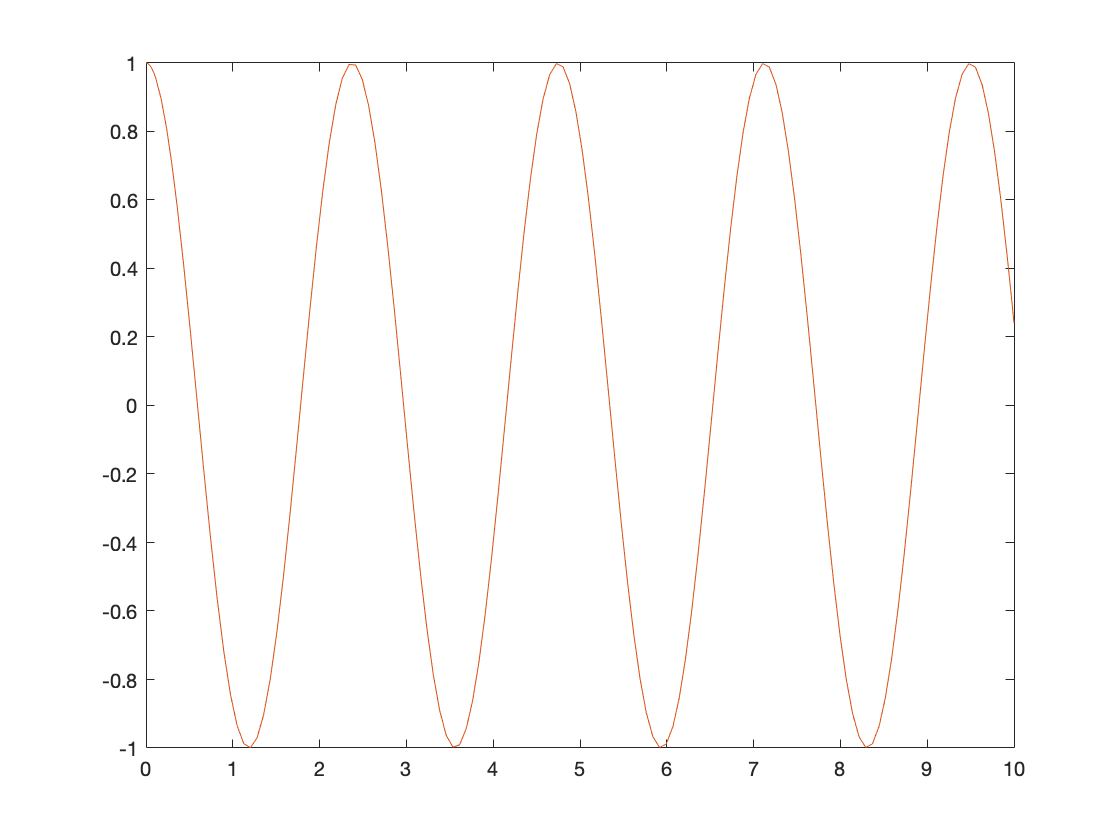

plot(t, y(:, N^2 - N + 1), t, y(:, N))

### Displaying the result

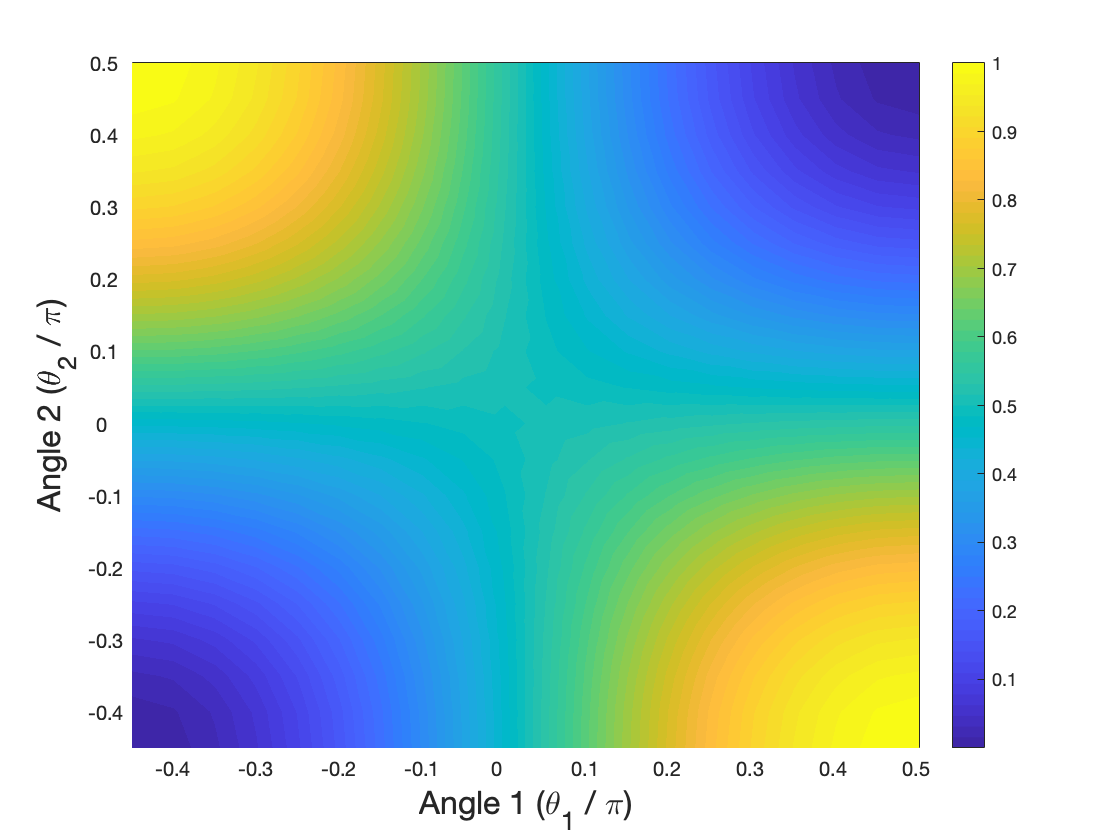

r = Result(t, y);
f = r.make_frame(J, 1);

### 50x50 Angular momentum matrices

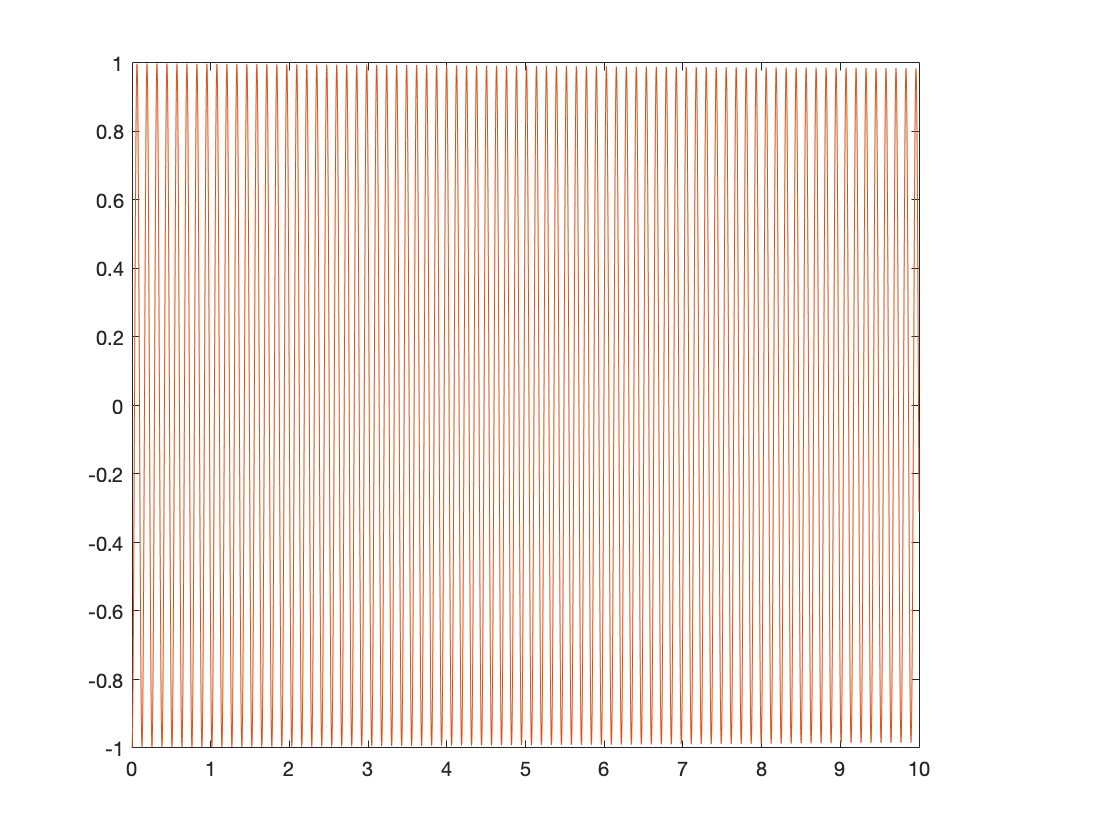

N = 50;
J = JMatrices(N);

n1 = [0, pi/2, 1];   % North pole
n2 = [0, -pi/2, 1];  % South pole

a = CoherentState(J, n1, CoordType.spherical);
b = CoherentState(J, n2, CoordType.spherical);
Phi = StringState(a, b);

m = 1;

tspan = [0, 10];
dPhi_dt_0 = zeros(N);
y0 = [Phi.M(:); dPhi_dt_0(:)];
[t, y] = solveEOM(tspan, y0, m, J);
plot(t, y(:, N^2 - N + 1), t, y(:, N))